## MAP55672 (2024-25) — Case studies 2

### 2.1 Arnoldi Iteration 

function [Q, H] = arnoldi(A, u, m)
% Arnoldi orthogonalization: Construct orthogonal basis Q and matrix H

    n = length(u);
    Q = zeros(n, m+1);
    H = zeros(m+1, m);
    Q(:,1) = u / norm(u); % Normalize the initial vector
    
    % Arnoldi iteration
    for j = 1:m
        v = A * Q(:,j);
        for i = 1:j
            H(i,j) = Q(:,i)' * v;  % Calculate the projection coefficient
            v = v - H(i,j) * Q(:,i); % Remove the already orthogonal part
        end
        H(j+1, j) = norm(v);  % Calculate the norm of the remaining vector
        
        % Stop early if the norm is 0
        if H(j+1, j) == 0
            Q = Q(:,1:j);
            H = H(1:j+1, 1:j);
            break;
        end
        Q(:, j+1) = v / H(j+1, j);  % Normalize the vector and use it as the new orthogonal vector
    end
end

**Test algorithm and determine *****Q*****9.**

A = [3 8 7 3 3 7 2 3 4 8;
     5 4 1 6 9 8 3 7 1 9;
     3 6 9 4 8 6 5 6 6 6;
     5 3 4 7 4 9 2 3 5 1;
     4 4 2 1 7 4 2 2 4 5;
     4 2 8 6 6 5 2 1 1 2;
     2 8 9 5 2 9 4 7 3 3;
     9 3 2 2 7 3 4 8 7 7;
     9 1 9 3 3 1 2 7 7 1;
     9 3 2 2 6 4 4 7 3 5];

x_true = [
    +0.757516242460009;
    +2.734057963614329;
    -0.555605907443403;
    +1.144284746786790;
    +0.645280108318073;
    -0.085488474462339;
    -0.623679022063185;
    -0.465240896342741;
    +2.382909057772335;
    -0.120465395885881
];

% Initial vector u = A * x_true, set number of iterations m = 9
u = A * x_true; m = 9;

% Arnoldi orthogonalization
[Q, H] = arnoldi(A, u, m);

% Extract Q9
Q9 = Q(:,10);
disp('Q9 is:'); disp(Q9);

Q9 is:
   -0.0984
   -0.1453
   -0.2519
   -0.0817
   -0.1399
    0.3577
    0.2745
    0.6858
   -0.2386
   -0.3858




% Check if Q is orthogonal
err = norm(Q(:,1:m)' * Q(:,1:m) - eye(m));
fprintf('The orthogonality error of Q is: %.2e\n', err);

The orthogonality error of Q is: 1.56e-15


### 2.2 Serial implementation of GMRES

function [x, res_history] = gmres(A, b, m)
% GMRES method: Approximate the solution to Ax = b in m steps
% Returns the approximate solution x and residual history

    n = length(b);
    x0 = zeros(n, 1);
    r0 = b - A*x0;        % Initial residual
    beta = norm(r0);      % Initial residual norm

    % Q and H for Arnoldi
    Q = zeros(n, m+1); H = zeros(m+1, m);
    Q(:, 1) = r0 / beta;
    res_history = zeros(m, 1); % Record the residual at each iteration

    for j = 1:m
         % Arnoldi orthogonalization
        w = A * Q(:, j);
        for i = 1:j
            H(i, j) = Q(:, i)' * w;
            w = w - H(i, j) * Q(:, i);
        end
        H(j+1, j) = norm(w);
        if H(j+1, j) < 1e-14
            % If the norm is very small, assume convergence
            break;
        end
        Q(:, j+1) = w / H(j+1, j);

        % Solve the least squares problem
        e1 = zeros(j+1, 1);
        e1(1) = 1;
        rhs = beta * e1;  % Right-hand side beta e1
        y_j = H(1:j+1, 1:j) \ rhs;  % Least squares solution
        % Record the current residual
        res_history(j) = norm(rhs - H(1:j+1, 1:j) * y_j);
    end

    % Final solution
    x = x0 + Q(:, 1:j) * y_j;
end

**Construct matrix and vectors**

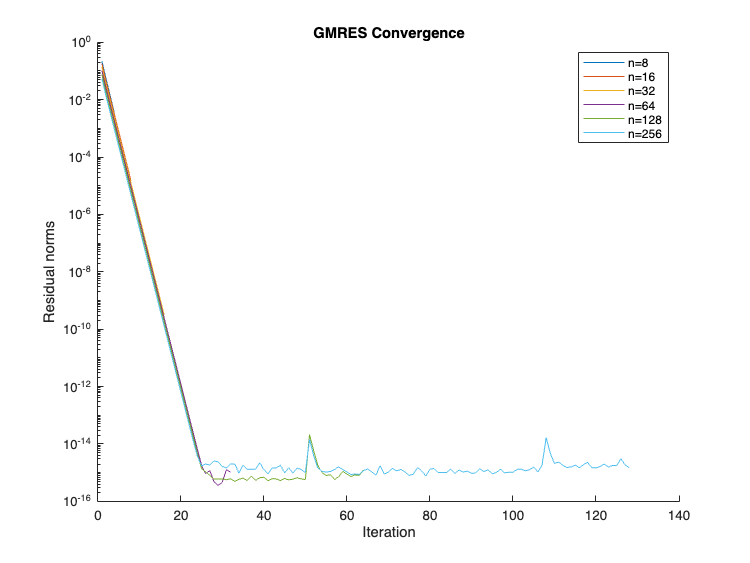

function A = build_matrix(n)
    A = diag(-4*ones(n,1)) + diag(ones(n-1,1),1) + diag(ones(n-1,1),-1);
end

function b = build_b(n)
    b = [(1:n-1)'/n; 1];
end

% test_gmres
warning off
n_values = [8, 16, 32, 64, 128, 256];
figure; hold on;
colors = lines(length(n_values));  

for idx = 1:length(n_values)
    n = n_values(idx);
    A = build_matrix(n);
    b = build_b(n);
    m = n/2;

    % Call GMRES
    [x_approx, res_hist] = gmres(A, b, m);

    % Calculate normalized residual
    norm_res = res_hist / norm(b);

    semilogy(1:length(norm_res), norm_res, '-', 'Color', colors(idx,:));
end

set(gca, 'YScale', 'log');
legend('n=8','n=16','n=32','n=64','n=128','n=256');
xlabel('Iteration');
ylabel('Residual norms');
title('GMRES Convergence');
hold off;

When n is small, GMRES converges quickly. When n is larger, GMRES still works, but it takes more iterations to reduce the residual. So, the convergence becomes slower as n increases.

### 2.3 Parallel implementation of GMRES.

function [x, res_history] = gmres_parallel(A, b, m)
% GMRES_PARALLEL: Parallel GMRES using parfor for matrix-vector product
    n = length(b);
    x0 = zeros(n,1);
    r0 = b - A*x0;
    beta = norm(r0);

    Q = zeros(n, m+1);
    H = zeros(m+1, m);
    Q(:,1) = r0 / beta;
    res_history = zeros(m, 1);

    for j = 1:m
        % Parallel matrix-vector product
        w = zeros(n, 1);
        parfor i = 1:n
            w(i) = A(i,:) * Q(:,j);
        end

        % Arnoldi orthogonalization
        for i = 1:j
            H(i,j) = Q(:,i)' * w;
            w = w - H(i,j) * Q(:,i);
        end
        H(j+1,j) = norm(w);
        if H(j+1,j) < 1e-14
            break;
        end
        Q(:,j+1) = w / H(j+1,j);

        % Least squares and residual
        e1 = zeros(j+1, 1); e1(1) = 1;
        rhs = beta * e1;
        y = H(1:j+1,1:j) \ rhs;
        res_history(j) = norm(rhs - H(1:j+1,1:j)*y);
    end

    x = x0 + Q(:,1:j) * y;
end

**GMRES Correctness**

function test_gmres_parallel(n)

    m = n / 2;
    A = build_matrix(n);
    b = build_b(n);

    % Serial GMRES
    tic;
    [x, res] = gmres(A, b, m);
    time = toc;

    % Parallel GMRES
    tic;
    [x_parallel, res_parallel] = gmres_parallel(A, b, m);
    time_parallel = toc;

    fprintf("=== GMRES Test ===\n");
    fprintf("n = %d, m = %d\n", n, m);
    fprintf("Serial time: %.4f s\n", time);
    fprintf("Parallel time: %.4f s\n", time_parallel);
    fprintf("||x - x_parallel|| = %.2e\n", norm(x - x_parallel));
    fprintf("||res - res_parallel|| = %.2e\n", norm(res - res_parallel));
    fprintf("Speedup: %.2fx\n", time / time_parallel);

    % Plot residuals
    figure;
    semilogy(1:length(res), res, '-o'); hold on;
    semilogy(1:length(res_parallel), res_parallel, '-x');
    legend('Serial', 'Parallel', 'Location', 'best');
    xlabel('Iteration');
    ylabel('Residual norms');
    title(sprintf('GMRES Residual Comparison (n = %d)', n));
    grid on;
end
warning off

**GMRES Convergence for Different n**

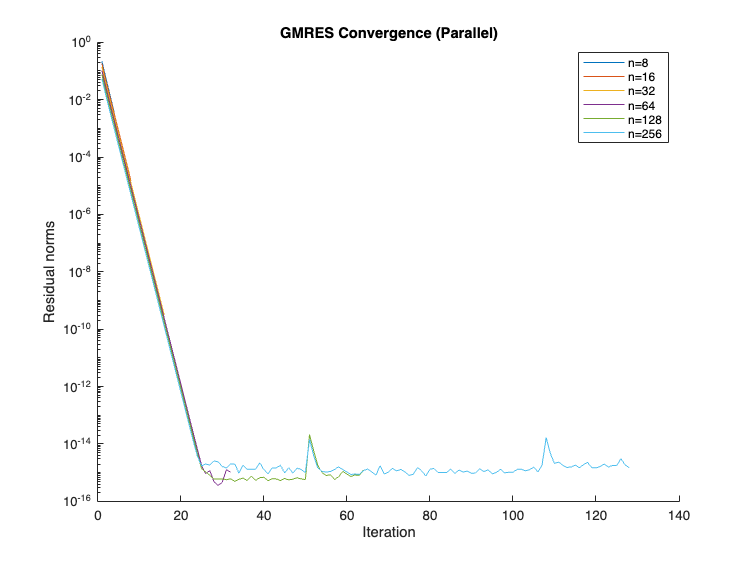

n_values = [8, 16, 32, 64, 128, 256];
figure; hold on;

for idx = 1:length(n_values)
    n = n_values(idx);
    m = n / 2;

    A = build_matrix(n);
    b = build_b(n);

    [x, res] = gmres(A, b, m);  
    norm_res = res / norm(b);

    semilogy(1:length(norm_res), norm_res, '-');
end

set(gca, 'YScale', 'log');
legend('n=8','n=16','n=32','n=64','n=128','n=256');
xlabel('Iteration');
ylabel('Residual norms');
title('GMRES Convergence (Parallel)');

** Runtime test and correctness**

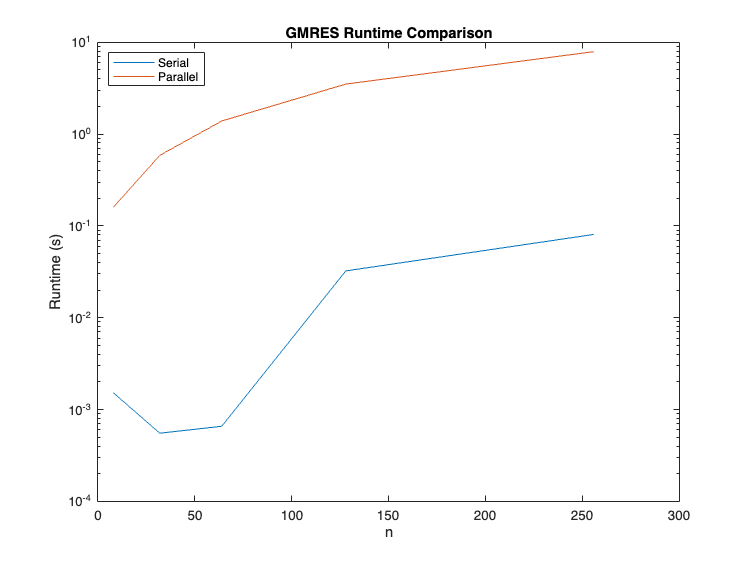

n_values = [8, 32, 64, 128, 256];
time_serial = zeros(size(n_values));
time_parallel = zeros(size(n_values));

for idx = 1:length(n_values)
    n = n_values(idx);
    m = n / 2;
    A = build_matrix(n);
    b = build_b(n);

    % Serial
    tic;
    gmres(A, b, m);
    time_serial(idx) = toc;

    % Parallel
    tic;
    gmres_parallel(A, b, m);
    time_parallel(idx) = toc;
end

figure;
semilogy(n_values, time_serial, '-'); hold on;
semilogy(n_values, time_parallel, '-');
legend('Serial', 'Parallel', 'Location', 'northwest');
xlabel('n');
ylabel('Runtime (s)');
title('GMRES Runtime Comparison');